# La cinétique de la saponification

Pascal Denis - mai 2020

## Introduction

Le Hall pilote est doté d'un banc réacteur, dont le PFD (Process Flow Diagram) est disponible sous Moodle, comprend 4 type de réacteurs : 

- 1 réacteur parfaitement agité d'un volume d'environ 800 ml

- 2 réacteurs parfaitement agités en cascade d'un volume respectif d'environ 400 ml

- 1 réacteur piston  d'un volume d'environ 900 ml

- 1 réacteur avec dispersion axial d'un volume de 900 ml

Vous vous contenterez de traiter les 2 premiers cas dans la suite de ce TP., car ne disposant pas de données enrgistrées, il vous sera impossible de comparer, quoique ...

## Réaction et Cinétique théorique

Vous allez travailler sur la saponification de l'acétate d'éthyle par la soude, en mileux basique.  La réaction, qui se fait en phase liquide, est la suivante : 

$CH_3COOC2H5 + NaOH \rightarrow C_2H_5OH + CH_3COONa$ (1)

À partir des articles disponibles sous Moodle, réunissez des éléments pour connaitre la cinétique de la réaction et proposer une équation pour la vitesse de réaction.  On notera A pour Acétate et B pour Base (Soude)

$r = k[C_A][C_B]
$ (2)

### Constante cinétique & loi d'Arrhénius 

En 2016-2017, les étudiants e l'option GEEN ont réalisé des TP sur un réacteur fermé et tempéré. Voici les températures (°C) et les constantes cinétiques (l/mol.s) qu'ils ont obtenus (T(°C) / k(mol/l.s))

— Gaëtan  & Charlotte  : 

- 20 / 0.1163  

- 37 / 0.2809

— Yoan  & Baptiste 

- 34 / 0.115   

- 19 / 0.043

— Camille  (son binôme étant arrivé avec 30 min de retard a été réfusé en TP ...)

- 15 / 0.034 

- 37 / 0.139

— Laura  & Aurelio 

- 30 / 0.1356 

- 38 / 0.211

— David  & Sophie 

- 21.5 / 0.137

— Eric  & Fabien 

- 37 / 0.199 

- 14  / 0.0784

A l'aide de ces données, estimer l'énergie d'activation de la réaction de saponification de l'acétate d'éthyle par la soude. Proposer alors une loi d'Arrhénius. 

data = [20 0.1163  
37 0.2809
34 0.115   
19 0.043
15 0.034  
37 0.139
30 0.1356 
38 0.211
21.5 0.137  
37 0.199  
14 0.0784];

T_C = data(:,1);
T_K = T_C + 273.15 ;
k_TP = data(:,2);


La loi d'arrhénius nous donne : 


$$k=k_{0\cdot } \exp \left(-\frac{\textrm{Ea}}{\textrm{RT}}\right)$$


on en déduit alors que : 


$$\log \left(k\right)=\log \left(k_0 \right)-\frac{\textrm{Ea}}{\textrm{RT}}$$


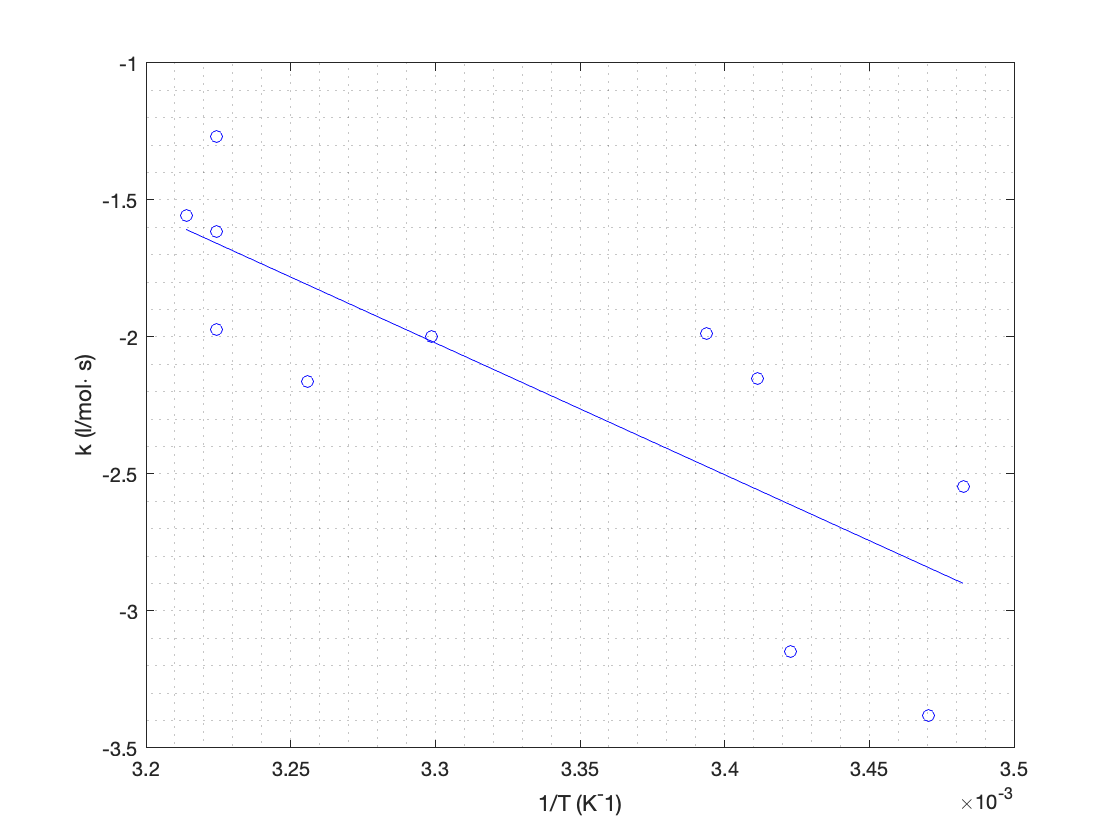

% Affichage 

plot (1./T_K, log(k_TP),'ob');
grid minor
xlabel('1/T (K^-1)')
ylabel('k (l/mol\cdot s)')
hold on

% Tracer de la droite 

droite = polyfit(1./T_K, log(k_TP),1);
plot(1./T_K, droite(1)./T_K + droite(2),'b')

% Energie d'activation 

R = 8.314462618; % Constante des gaz parfaits  :  CODATA 2019
EA_0 = -droite(1) * R

EA_0 =      3.998787273862420e+04


k_0_0 = exp(droite(2))

k_0_0 =      1.034473172981696e+06


### Comparatif avec la littérature scientifique, mais pas que ...

Nous avons "pléthores" d'informations à notre dispositions : 

- Des mesures complémentaires ont été obtenues [1] et [2]. 

- Un TP d'étudiant présenté sous forme d'article scientifique propose des résultats pour la constante et l'énergie d'activation [3]

- Un article issu du web, sans référence donne : 


$$k_0 =18\ldotp 6{\;{10}^6 \;m}^3 /\textrm{kmol}\cdot s$$



$$\textrm{Ea}=4\ldotp 688\times {10}^4 \;J/\textrm{mol}$$


- Enfin, l'énoncé de TP de l'IUT de Génie des Procédés propose quant à lui : 


$$k=1\ldotp 7998\;{10}^8 \;\exp \left(-\frac{5200}{T}\right)\;\;l/\textrm{mol}\cdot \min$$


Que pensez-vous de l'ensemble de ces données.

Représentez et visualiser les différentes propositions,

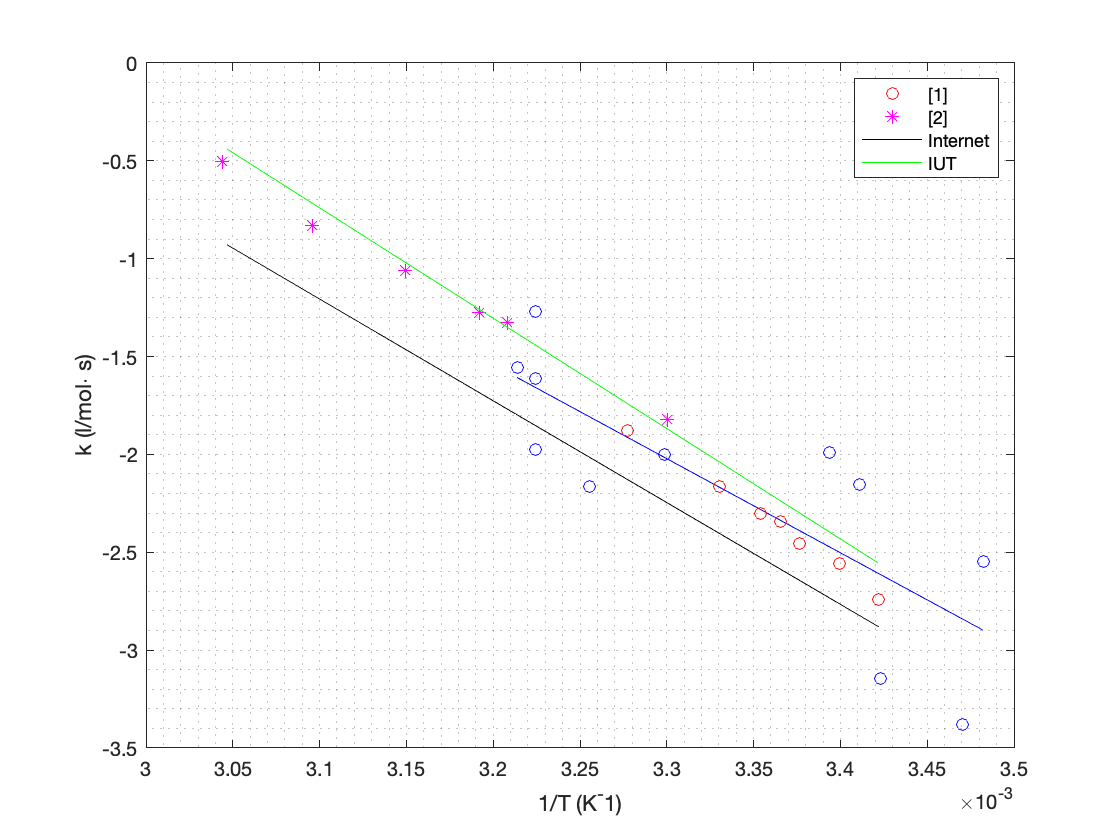

T_1 = [292.25
294.15
296.15
297.15
298.15
300.25
305.15];

k_1 = [0.0646
0.0775
0.086
0.096
0.1
0.115
0.153];

EA_1 = 48700 ; % J/mol
k_0_1 = 2E09/60; % l/mol.s

T_2 = [303
311.7
313.3
317.5
323
328.5];

k_2 = [0.162
0.266
0.28
0.346
0.437
0.603];

EA_2 = 41400 ; % J/mol
k_0_2 = 2.4789e+06;% l/mol.s

T = [T_1  
    T_2];
k = [k_1  
    k_2];

EA_3 = 5200 * R;
k_0_3 = 1.7998E8/60 ; %l/mol.s

EA_4 = 46880;
k_0_4 = 18.6E6;

T_cin = min(T):1:max(T);

k_exp_3 = k_0_3 .* exp(-EA_3/R./T_cin);
k_exp_4 = k_0_4 .* exp(-EA_4/R./T_cin);

PLOT_K1 =  plot(1./T_1,log(k_1),'or');
PLOT_K2 =  plot(1./T_2,log(k_2),'*m');
PLOT_K3 =  plot(1./T_cin, log(k_exp_3),'k');
PLOT_K4 =  plot(1./T_cin, log(k_exp_4),'g');

legend([PLOT_K1,PLOT_K2,PLOT_K3,PLOT_K4],'[1]', '[2]', 'Internet','IUT','location','northeast');
hold off

## Réacteur ouvert

Pour la production industrielle, on utilisera de 1 à 3 réacteurs parfaitement agités en  série, déterminer alors la concentration de soude et d'acétate dans chacun des réacteurs

L'équation de la saponification s'écrit simplement : 


$${\textrm{CH}}_3 \textrm{COO}C_2 H_5 \;+\textrm{NaOH}\longrightarrow {\textrm{CH}}_3 {\textrm{COONa}\;\textrm{+}\;\textrm{C}}_2 H_5 \textrm{OH}$$


qui sera simplifiée par : 

 
$$A+B\longrightarrow C+D$$


La loi cinétique est donnée par la littérature[1] sous la forme : 


$$r=kC_A C_B$$


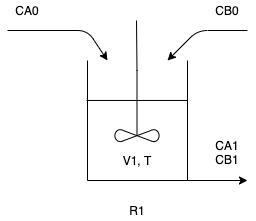

Figure 1 : Schéma de principe d'un RPA

## Cas d'un réacteur

V1 = 0.8; % l 

% Débit volumique initiaux

VA0 = 15 ; % l/h
VB0 = 15 ; % l/h

VA0 = VA0 / 3600;% l/s
VB0 = VB0 / 3600;% l/s

% Concentration initial

CA0 = 0.12; % mol/l
CB0 = 0.16; % mol/l


% En phase liquide,  on peut considérer une invariance du débit volumique 

V = VA0 + VB0;

% Température de travail 

T = 25; % Celsius
T_K = T + 273.15 ;% Kelvin


k0 = k_0_1; % m3/kmol.s
Ea = EA_1; % J/mol

k = k0 * exp(-Ea/R/T_K); % m3/kmol.s  =  l/mol.S


## Bilan Matière

Écrire le bilan matière en régime transitoire

Le bilan s'écrit pour l'aétate d'éthyle à vous de le retrouver !  

$\frac{{\textrm{dC}}_{\textrm{A1}} }{\textrm{dt}}=\frac{1}{V_1 }\left({\overset{\ldotp }{V} }_{\textrm{A0}} C_{\textrm{A0}} -\overset{\ldotp }{V} C_{\textrm{A1}} -{V_1 \textrm{kC}}_{\textrm{A1}} C_{\textrm{B1}} \right)$(1)

et de même pour la soude :

$\frac{{\textrm{dC}}_{B\mathrm{1}} }{\textrm{dt}}=\frac{1}{V_1 }\left({\overset{\ldotp }{V} }_{B\mathrm{0}} C_{B\mathrm{0}} -\overset{\ldotp }{V} C_{B\mathrm{1}} -{V_1 \textrm{kC}}_{\textrm{A1}} C_{\textrm{B1}} \right)$(2)

Effectuer alors la résolution de ce système d'équations différentielles. 

dCdt = @(t,C) [(VA0*CA0-V*C(1)-k*V1*C(1)*C(2))/V1; % eq (1)
               (VB0*CB0-V*C(2)-k*V1*C(1)*C(2))/V1]; % eq (2)

tspan = 0:1:1000 ; %interval de calcul en temps


%C0 = [CA0* VA0/(VA0 + VB0) CB0 * VA0/(VA0 + VB0)]; % condition initial de concentration réservoir plein ...
C0 = [0    0 ]; % condition initial de concentration réservoir plein d'eau
%C0 = [CA0     0 ]; % condition initial de concentration réservoir plein
%d'acétate
%C0 = [0    CB0  ]; %condition initial de concentration réservoir plein de
%soude
    
[t,C] = ode45(dCdt, tspan, C0);


plot(t,C(:,1),'r');
hold on 
plot(t,C(:,2),'b');
xlabel('Time(s)'), ylabel('Concentration(mol/l)')
grid minor
legend('C_{A1}','C_{B1}', 'Location',"southeast");
hold off

### Taux de conversion (théorique)

À partir des informations précédentes, déterterminer le taux de conversion théorique maximal. 

CA1_S = C(end, 1); 
CB1_S = C(end, 2); 

FA1_S =  CA1_S * (VA0 + VB0);
FB1_S =  CB1_S * (VA0 + VB0);

FA0 = VA0 * CA0;
FB0 = VB0 * CB0;

x_A = (FA0 - FA1_S) / FA0 


## Cas de 2 ou 3 réacteurs en cascades

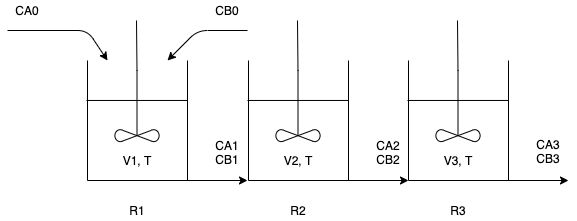

Figure 2 : Schéma de principe de 3 réacteurs RPA en cascade

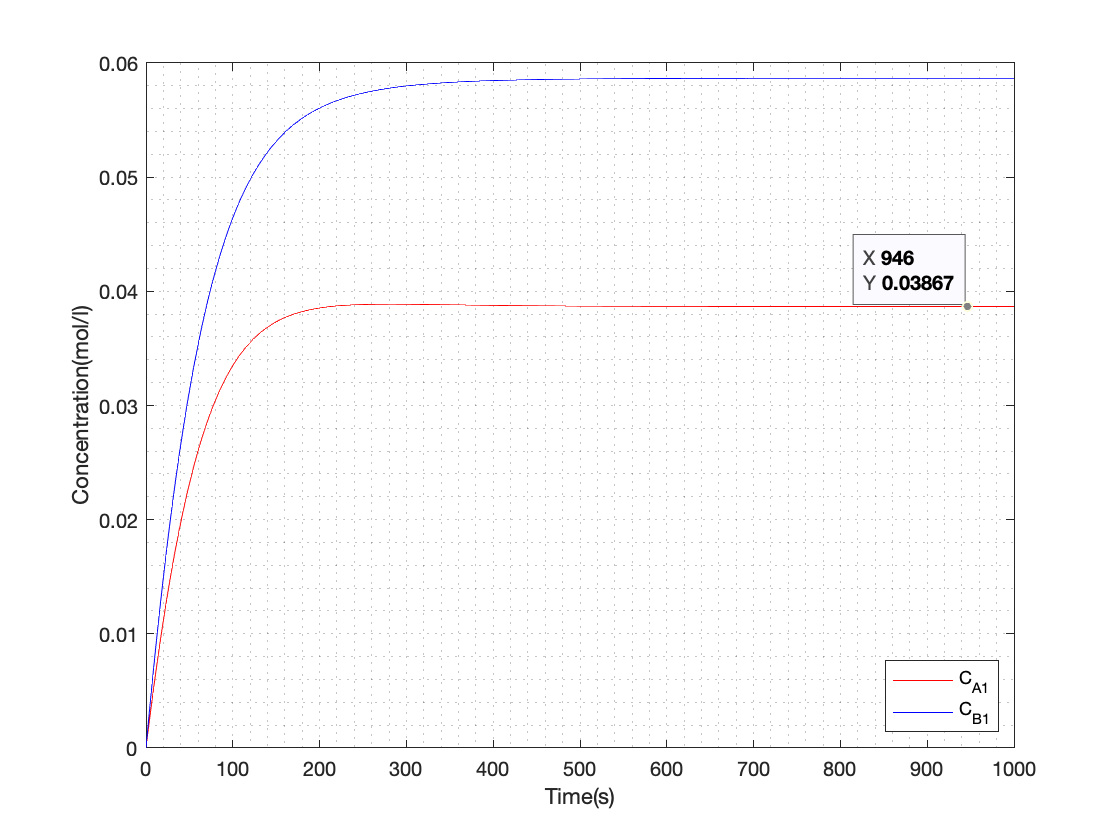

V1 = 0.800 ; % l 
V2 = 0.400; % l
V3 = 0.5; % l

% Débit volumique initiaux

VA0 = 10; % l/h
VB0 = 10; % l/h

VA0 = VA0 / 3600;% l/s

VB0 = VB0 / 3600;% l/s

% Concentration initial

CA0 = 0.12; % mol/l
CB0 = 0.16; % mol/l

% En phase liquide,  on peut considérer une invariance du débit volumique 

V = VA0 + VB0;

% Température de travail 

T = 37; % Celsius

x_A =    0.401797452839351


T_K = T + 273.15 ;% Kelvin


k = k0 * exp(-Ea/R/T_K); % m3/kmol.s  =  l/mol.S



## Bilan Matière

Le bilan s'écrit pour l'aétate d'éthyle : 

$\frac{{\textrm{dC}}_{\textrm{A1}} }{\textrm{dt}}=\frac{1}{V_1 }\left({\overset{\ldotp }{V} }_{\textrm{A0}} C_{\textrm{A0}} -{\overset{\ldotp }{V} }_{\mathrm{1}} C_{\textrm{A1}} -{V_1 \textrm{kC}}_{\textrm{A1}} C_{\textrm{B1}} \right)$(1)

$\frac{{\textrm{dC}}_{\mathrm{A}2} }{\textrm{dt}}=\frac{1}{V_2 }\left({\overset{\ldotp }{V} }_1 C_{\mathrm{A}1} -{\overset{\ldotp }{V} }_2 C_{\mathrm{A}2} -{V_2 \textrm{kC}}_{\mathrm{A}2} C_{\mathrm{B}2} \right)$(2)

$\frac{{\textrm{dC}}_{\mathrm{A}3} }{\textrm{dt}}=\frac{1}{V_3 }\left({\overset{\ldotp }{V} }_2 C_{\mathrm{A}2} -{\overset{\ldotp }{V} }_3 C_{\mathrm{A}3} -{V_3 \textrm{kC}}_{\mathrm{A}3} C_{\mathrm{B}3} \right)$(3)

et de même pour la soude :

$\frac{{\textrm{dC}}_{B\mathrm{1}} }{\textrm{dt}}=\frac{1}{V_1 }\left({\overset{\ldotp }{V} }_{B\mathrm{0}} C_{B\mathrm{0}} -{\overset{\ldotp }{V} }_{\mathrm{1}} C_{B\mathrm{1}} -{V_1 \textrm{kC}}_{\textrm{A1}} C_{\textrm{B1}} \right)$(4)

$\frac{{\textrm{dC}}_{B2} }{\textrm{dt}}=\frac{1}{V_2 }\left({\overset{\ldotp }{V} }_1 C_{B1} -{\overset{\ldotp }{V} }_2 C_{B2} -{V_2 \textrm{kC}}_{\mathrm{A}2} C_{\mathrm{B}2} \right)$(5)

$\frac{{\textrm{dC}}_{B3} }{\textrm{dt}}=\frac{1}{V_3 }\left({\overset{\ldotp }{V} }_2 C_{B2} -{\overset{,}{V} }_3 C_{B3} -{V_3 \textrm{kC}}_{\mathrm{A}3} C_{\mathrm{B}3} \right)$(6)

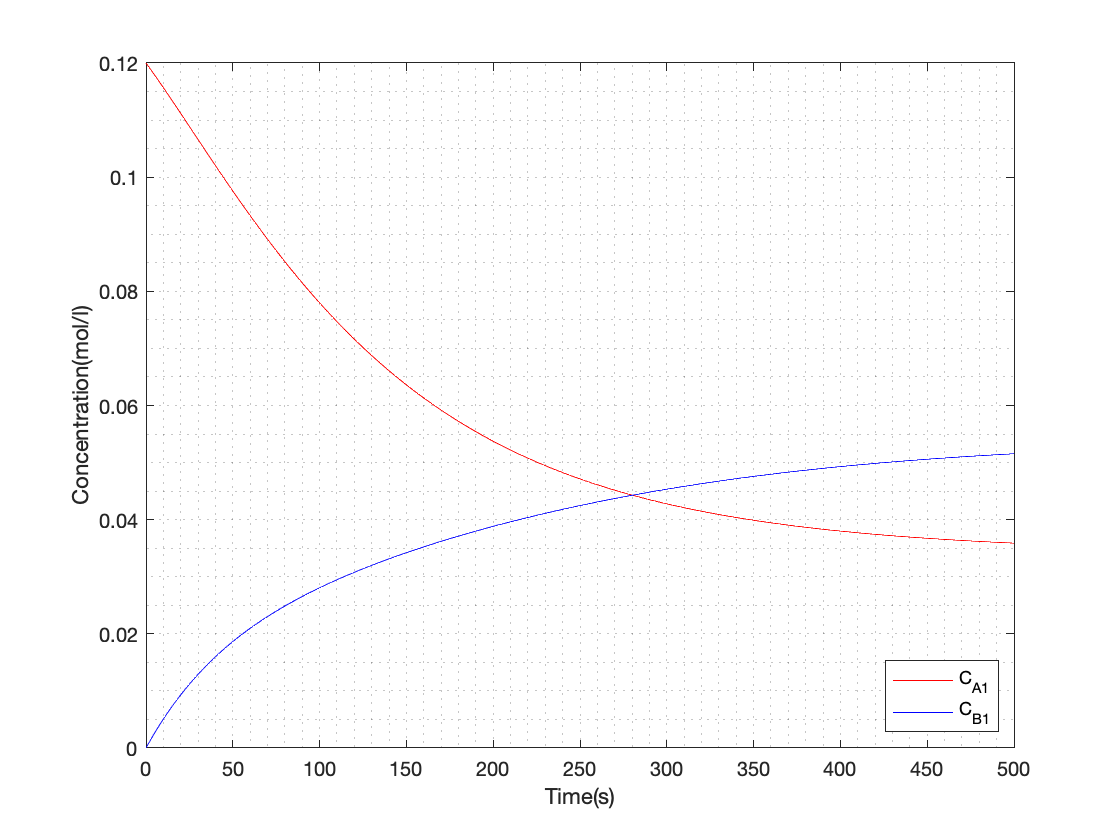

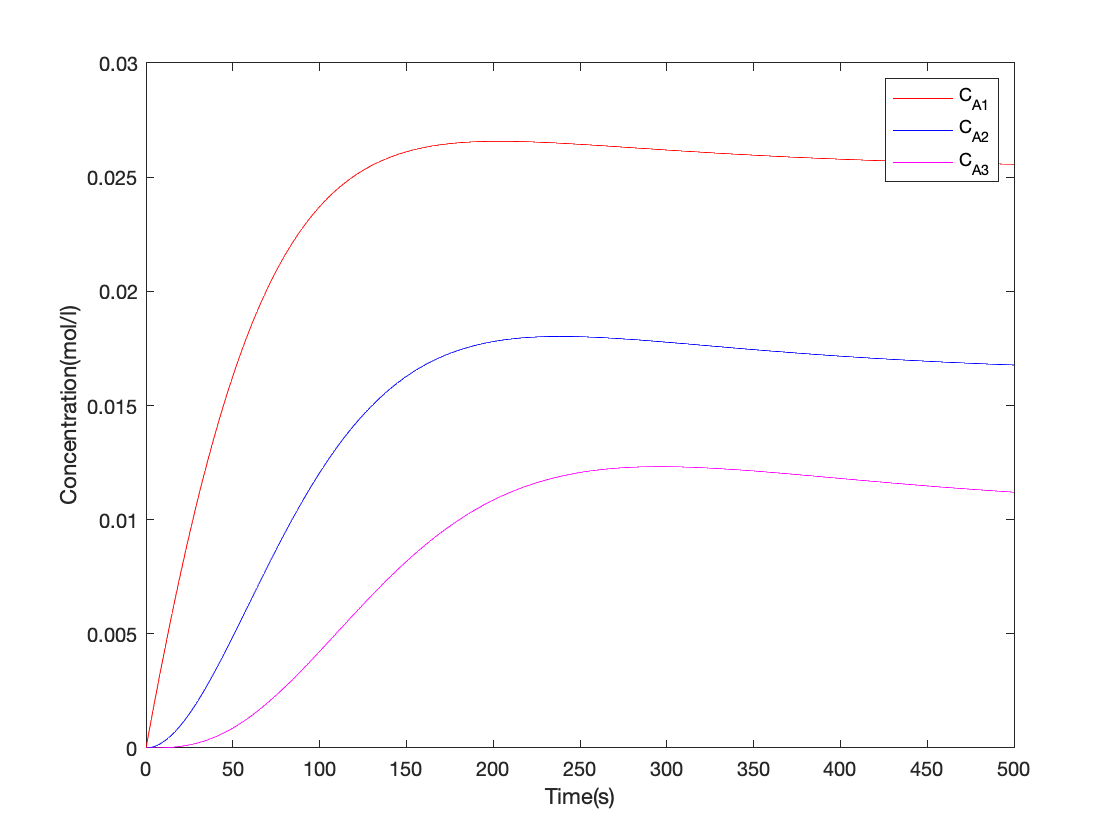

dCdt = @(t,C) [(VA0*CA0-V*C(1)-k*V1*C(1)*C(2))/V1; % eq (1)
               (VB0*CB0-V*C(2)-k*V1*C(1)*C(2))/V1; % eq (4)
  (V*C(1)-V*C(3)-k*V2*C(3)*C(4))/V2;% eq (2)
  (V*C(2)-V*C(4)-k*V2*C(3)*C(4))/V2;% eq (5)
  (V*C(3)-V*C(5)-k*V3*C(5)*C(6))/V3;% eq (3)
  (V*C(4)-V*C(6)-k*V3*C(5)*C(6))/V3];% eq (6)


tspan = 0:1:500 ; %interval de calcul en temps
C0 = [0 0 0 0 0 0 ]; %condition initial de concentration

[t,C] = ode45(dCdt, tspan, C0);

hold off
plot(t,C(:,1),'-r',t,C(:,3),'-b',t,C(:,5),'-m');
xlabel('Time(s)'), ylabel('Concentration(mol/l)')
legend('C_{A1}','C_{A2}','C_{A3}');

## Bibliographie 

[1]	A. Petek, M. Krajnc, [The enthalpy and entropy of activation for ethyl acetate saponification](https://moodle.centrale-marseille.fr/pluginfile.php/731/mod_resource/content/1/The%20enthalpy%20and%20entropy%20of%20activation%20for%20ethyl%20acetate%20saponification-Petek-2012.pdf), Int. J. Chem. Kinet. 44 (2012) 692–698. doi:10.1002/kin.20712.

[2]	K. Das, P. Sahoo, M.S. Baba, N. Murali, P. Swaminathan, [Kinetic studies on saponification of ethyl acetate using an innovative conductivity-monitoring instrument with a pulsating sensor](https://moodle.centrale-marseille.fr/pluginfile.php/730/mod_resource/content/1/Kinetic%20studies%20on%20saponification%20of%20ethyl%20acetate%20using%20an%20innovative%20conductivity-monitoring%20instrument%20with%20a%20pulsating%20sensor-Das-2011.pdf), Int. J. Chem. Kinet. 43 (2011) 648–656. doi:10.1002/kin.20597.

[3]	A. Mukhtar, U. Shafiq, A. F. Khan, H. Q. R. J. of, 2015, Estimation of parameters of Arrhenius equation for ethyl acetate saponification reaction 